Cases = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
Cases = table2array(Cases(:,[13:173])); 
Cases = max(Cases,[], 2);


Deaths = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Deaths_CC.csv', 'ReadVariableNames',1);
Deaths = table2array(Deaths(:,[13:173])); 
Deaths = max(Deaths,[],2);

Confounding = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);

% Data = Confounding;
% Data.Cases = Cases;
% Data.Deaths = Deaths; 
% 
% Data(:,[4:14]); 
% Data = table2array(Data(:,[4:14]));

Total_Population = (Confounding.TOT_POP);
Pop_Density = (Confounding.POP_DENSITY);
Black_Pct = (Confounding.BLACK_PCT);
Hisp_Pct = (Confounding.HISPANIC_PCT);
Over_70_Pct = (Confounding.OVER_70_PCT);
Health_Ins_Pct = (Confounding.HLTH_INS_PCT); 
Poverty_Pct = (Confounding.PCT_POVERTY);

**COVID RELATIONSHIPS**

% Cases vs total pop % 
c = corrcoef(Cases, Total_Population); 
c = c(1,2);
fprintf('Correlation coefficent between cases and total population is %f \n', c)

figure(1)
subplot(2,1,1)
plot(Total_Population,Cases, '*')
ylim([0,60000])
title('Cases vs Total Population')
ylabel('Cases')
xlabel('Total_Population')

% Deaths vs total pop% 
c = corrcoef(Deaths, Total_Population);
c = c(1,2);
fprintf('Correlation coefficent between deaths and total population is %f \n', c)

subplot(2,1,2)
plot(Total_Population,Deaths, '*')
title('Deaths vs Total Population')
ylim([0,3000])
ylabel('Deaths')
xlabel('Total Population')

Cases = (Cases./Total_Population)*1000;
Deaths = (Deaths./Total_Population)*1000;

c = corrcoef(Cases, Total_Population); 
c = c(1,2);
fprintf('After Normalization the correlation coefficent between cases and total population is %f \n', c)

c = corrcoef(Deaths, Total_Population);
c = c(1,2);
fprintf('After Normalization the correlation coefficent between deaths and total population is %f \n', c)

% Cases vs pop density% 
c = corrcoef(Cases, Pop_Density); 
c = c(1,2);
fprintf('Correlation coefficent between cases and population desnsity is %f \n', c)

figure(2)
subplot(2,1,1)
plot(Pop_Density,Cases, '*')
title('Cases vs Population Density')
ylabel('Cases')
xlabel('Population Density')

% Deaths vs total pop% 
c = corrcoef(Deaths, Pop_Density);
c = c(1,2);
fprintf('Correlation coefficent between deaths and population density is %f \n', c)

subplot(2,1,2)
plot(Pop_Density,Deaths, '*')
title('Deaths vs Population Density')
ylabel('Deaths')
xlabel('Population Density')

% Cases vs black pct % 
c = corrcoef(Cases, Black_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and black percent of the population is %f \n', c)

figure(3)
subplot(2,1,1)
plot(Black_Pct,Cases, '*')
title("Cases vs Black Percent of Population")
ylabel('Cases')
xlabel('Black Percent of Population')

% Deaths vs black pct% 
c = corrcoef(Deaths, Black_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and black percent of the population is %f \n', c)

subplot(2,1,2)
plot(Black_Pct,Deaths, '*')
title("Deaths vs Black Percent of Population")
ylabel('Deaths')
xlabel('Black Percent of Population')

% Cases vs Hispanic pct % 
c = corrcoef(Cases, Hisp_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and hispanic percent of the population is %f \n', c)

figure(4)
subplot(2,1,1)
plot(Hisp_Pct,Cases, '*')
title("Cases vs Hispanic Percent of Population")
ylabel('Cases')
xlabel('Hispanic Percent of Population')

% Deaths vs Hispanic pct% 
c = corrcoef(Deaths, Hisp_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and hispanic percent of the population is %f \n', c)

subplot(2,1,2)
plot(Hisp_Pct,Deaths, '*')
title("Deaths vs Hispanic Percent of Population")
ylabel('Deaths')
xlabel('Hispanic Percent of Population')

% Cases vs pct over 70 % 
c = corrcoef(Cases, Over_70_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and percent of the population over 70 is %f \n', c)

figure(5)
subplot(2,1,1)
plot(Over_70_Pct,Cases, '*')
title("Cases vs Percent of Population Over 70")
ylabel('Cases')
xlabel('Percent of Population Over 70')

% Deaths vs over 70 pct% 
c = corrcoef(Deaths, Over_70_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and percent of the population over 70 is %f \n', c)

subplot(2,1,2)
plot(Over_70_Pct,Deaths,'*')
title("Deaths vs Percent of Population Over 70")
ylabel('Deaths')
xlabel('Percent of Population Over 70')

% Cases vs Health Insurance pct % 
c = corrcoef(Cases, Health_Ins_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and percent of the population with health insurance is %f \n', c)

figure(6)
subplot(2,1,1)
plot(Health_Ins_Pct,Cases, '*')
title("Cases vs Percent of Population With Health Insurance")
ylabel('Cases')
xlabel('Percent of Population With Health Insurance')

% Deaths vs Health Insurance pct% 
c = corrcoef(Deaths, Health_Ins_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and percent of the population with health insurance is %f \n', c)

subplot(2,1,2)
plot(Health_Ins_Pct,Deaths, '*')
title("Deaths vs Percent of Population With Health Insurance")
ylabel('Deaths')
xlabel('Percent of Population With Health Insurance')

% Cases vs Poverty pct % 
c = corrcoef(Cases, Poverty_Pct);
c = c(1,2);
fprintf('Correlation coefficent between cases and percent of the population in poverty is %f \n', c)

figure(6)
subplot(2,1,1)
plot(Poverty_Pct,Cases,'*')
title("Cases vs Percent of Population in Poverty")
ylabel('Cases')
xlabel('Percent of Population in Poverty')

% Deaths vs Poverty pct% 
c = corrcoef(Deaths, Poverty_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and percent of the population in poverty is %f \n', c)

subplot(2,1,2)
plot(Poverty_Pct,Deaths, '*')
title("Deaths vs Percent of Population in Poverty")
ylabel('Deaths')
xlabel('Percent of Population in Poverty')

T = table(Cases, Deaths)

T = 832×2 table
     Cases       Deaths  
    ________    _________

       3.073     0.040316
      6.6617     0.090512
       8.418     0.069917
      6.1114      0.12712
      4.0989     0.047222
      6.6614      0.21258
      2.8345      0.01609
       8.947      0.32429
       16.95      0.41504
      8.1969     0.025067
      8.3504            0
      4.9701      0.10565
       22.21      0.96564
      9.7872      0.17196
      33.121       1.1963
      5.2175     0.063531
      13.528      0.64122
      5.7203     0.092562
      16.345      0.23688
      11.652      0.17189
      5.3822       0.4006
      33.383       1.1269
      8.0084      0.26068
      8.1614      0.14477
      38.754      0.47314
       3.322     0.038282
      30.395      0.43969
      2.5538            0
      15.619      0.25023
     0.77389            0
      3.7568      0.05009
      5.3073      0.14799
      6.4371      0.33607
     

%writetable(T, '/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Normalized_Cases_Deaths.csv'); 

**AQI RELATIONSHIPS **

AQI_data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/AQI_Features.csv')

AQI_data = 832×8 table
         State                  County                          CS                   MaxAQI    x90thPercentileAQI    MedianAQI    AQI_Class_KM    Extreme_AQI
    ________________    ______________________    _______________________________    ______    __________________    _________    ____________    ___________

    'Alabama'           'Baldwin'                 'BaldwinAlabama'                    129      52.667                 36.833      1               0          
    'Alabama'           'Colbert'                 'ColbertAlabama'                    115      49.667                 36.667      1               0          
    'Alabama'           'DeKalb'                  'DeKalbAlabama'       

med_AQI = AQI_data.MedianAQI;

med_AQI =    36.8333
   36.6667
   38.0000
   44.1667
   35.1667
   51.5000
   40.1667
   39.8333
   46.0000
   39.0000


% AQI vs Poverty
c = corrcoef(med_AQI, Poverty_Pct);
c = c(1,2);
fprintf('Correlation coefficent between median AQI and percent of the population in poverty is %f \n', c)

Correlation coefficent between median AQI and percent of the population in poverty is 0.034720 


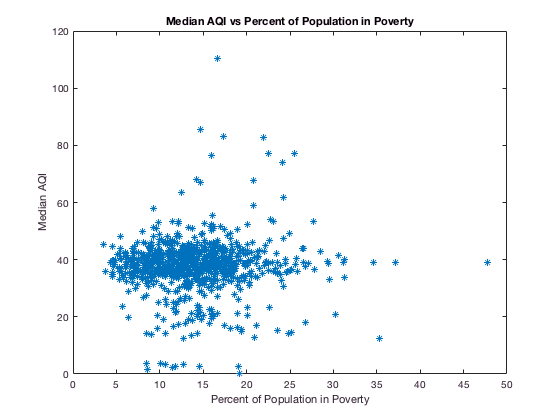


plot(Poverty_Pct,med_AQI, '*')
title("Median AQI vs Percent of Population in Poverty")
ylabel('Median AQI')
xlabel('Percent of Population in Poverty')


% AQI vs Health Insurance
c = corrcoef(med_AQI, Health_Ins_Pct);
c = c(1,2);
fprintf('Correlation coefficent between median AQI and percent of the population with health insurance is %f \n', c)

Correlation coefficent between median AQI and percent of the population with health insurance is -0.015969 


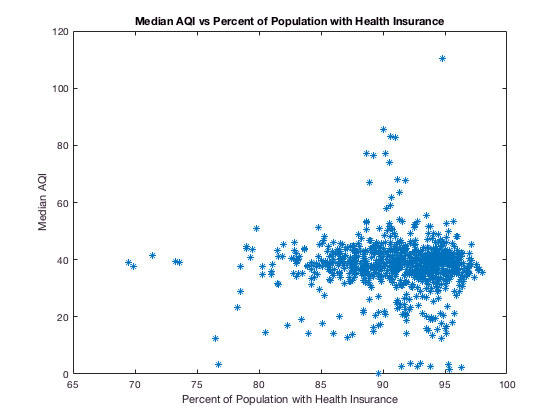


plot(Health_Ins_Pct,med_AQI, '*')
title("Median AQI vs Percent of Population with Health Insurance")
ylabel('Median AQI')
xlabel('Percent of Population with Health Insurance')